clear
load jumps.mat

Acceleration.time=timeElapsed(Acceleration.Timestamp);
Acc=Acceleration{:,["time", "X" ,"Y" ,"Z"]};
Acc=Acc(Acc(:,1)>10 & Acc(:,1)<20,:);

Acc =    10.0730   -0.8865   -9.9518   -0.1798
   10.1730   -0.7771  -10.0361   -0.1786
   10.2730   -0.2704  -10.2547    0.2566
   10.3730    0.1564   -9.9368    1.7429
   10.4730    1.2359   -7.2242    1.7028
   10.5730   -1.1782   -6.8010    3.2222
   10.6720    5.5427  -12.5148    3.1448
   10.7720    3.1481  -23.0997    5.5202
   10.8720   -0.1373  -15.0613    3.5853
   10.9720    1.5751    0.5719    3.2183


Acc_ =    10.0730    9.9928
   10.1730   10.0677
   10.2730   10.2615
   10.3730   10.0897
   10.4730    7.5244
   10.5730    7.6174
   10.6720   14.0439
   10.7720   23.9579
   10.8720   15.4828
   10.9720    3.6285


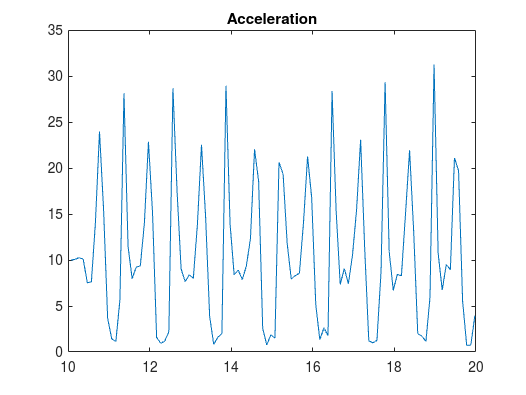

Acc_=[Acc(:,1),sqrt((Acc(:,2)).^2+(Acc(:,3)).^2+(Acc(:,4)).^2)];


[rows,~]=size(Acc_);
high_points=[0 0];
bottom_points=[0 100];
avg_value=mean(Acc_(:,2));

avg_value = 10.4374

flag=1;
top=[0 0];
bottom=[0 100];
for i=1:rows
    if flag==1
        if Acc_(i,2) >avg_value
            if Acc_(i,2)>top(2)
                top=Acc_(i,:);
            end
        else
            high_points=[high_points; top];
            flag=0;
            top=[0 0];
            if Acc_(i,2)<bottom(2)
                bottom=Acc_(i,:);
            end
        end
    else
        if Acc_(i,2)<=avg_value
            if Acc_(i,2)<bottom(2)
                bottom=Acc_(i,:);
            end
        else
            bottom_points=[bottom_points;bottom];
            flag=1;
            bottom=[0 100];
            if Acc_(i,2)>top(2)
                top=Acc_(i,:);
            end
        end
    end
end
high_points=high_points(2:end,:);

high_points =          0         0
   10.7720   23.9579
   11.3720   28.1200
   11.9720   22.8570
   12.5720   28.6593
   13.2720   22.5281
   13.8720   28.9399
   14.5720   22.0363
   15.1720   20.6274
   15.8720   21.2557


[rows_top,~]=size(high_points);

rows_top = 16

bottom_points=bottom_points(2:end,:);

bottom_points =    10.4730    7.5244
   11.1720    1.1458
   11.5720    7.9669
   12.2720    0.9514
   12.8720    7.6507
   13.5720    0.8105
   14.2720    7.8736
   14.8720    0.7750
   15.4720    7.9286
   16.1720    1.3297


[rows_bot,~]=size(bottom_points);

rows_bot = 15

duration=[];


duration =

     []



step_height=[];


step_height =

     []



for i=2:rows_top-1
    dur=(-high_points(i-1,1)+high_points(i+1,1))/2;
    height=(high_points(i,2)-bottom_points(i-1,2)+high_points(i,2)-bottom_points(i,2))/2;
    duration=[duration,dur];
    step_height=[step_height, height];
end
duration=duration(2:end)';

duration =     0.6000
    0.6000
    0.6500
    0.6500
    0.6500
    0.6500
    0.6500
    0.6500
    0.6500
    0.6500


step_height=step_height(2:end)';

step_height =    23.5636
   18.3979
   24.3582
   18.2975
   24.5978
   17.7120
   16.2756
   16.6265
   24.0229
   18.9046


result4=[duration, step_height]

result =     0.6000   23.5636
    0.6000   18.3979
    0.6500   24.3582
    0.6500   18.2975
    0.6500   24.5978
    0.6500   17.7120
    0.6500   16.2756
    0.6500   16.6265
    0.6500   24.0229
    0.6500   18.9046
